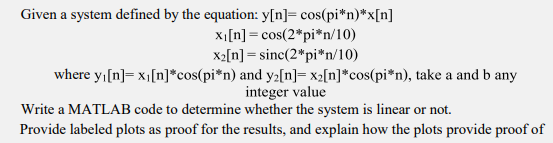

Given a system defined by the equation:

 y[n]= cos(pi**n)*x[n] *

*x1[n] = cos(2*pi**n/10) 

x2[n] = sinc(2**pi**n/10)

` where y1[n]= x1[n]*cos(pi*n) `

`and `

`y2[n]= x2[n]*cos(pi*n)`

`, take a and b any integer value`

Write a MATLAB code to determine whether the system is linear or not.

Provide labeled plots as proof for the results, and explain how the plots provide proof of linearity.

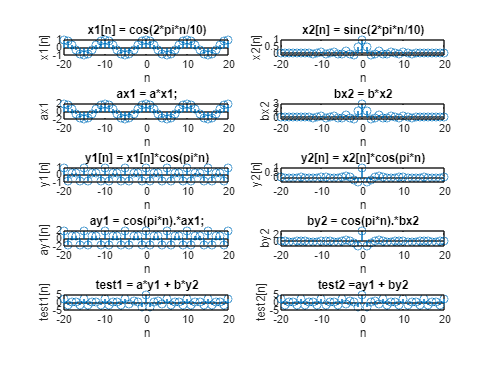

% Given system defined by the equation
% y[n] = cos(pi*n)*x[n]
% x1[n] = cos(2*pi*n/10)
% x2[n] = sinc(2*pi*n/10)

% Define the range of n
n = -20:20;

a = 2; % Choose arbitrary value for a
b = 3; % Choose arbitrary value for b

% Define the input signals
x1 = cos(2*pi*n/10);
x2 = sinc(2*pi*n/10);

% Define the output signals
y1 = x1.*cos(pi*n);
y2 = x2.*cos(pi*n);

%defining ax1 and ax2
ax1 = a*x1;
bx2 = b*x2;

ay1 = cos(pi*n).*ax1;
by2 = cos(pi*n).*bx2;

% Determine whether the system is linear or not

test1 = a*y1 + b*y2;
test2 = ay1 + by2;

% Plot the input signals
subplot(5, 2, 1);
stem(n, x1);
title('x1[n] = cos(2*pi*n/10)');
xlabel('n');
ylabel('x1[n]');

subplot(5, 2, 2);
stem(n, x2);
title('x2[n] = sinc(2*pi*n/10)');
xlabel('n');
ylabel('x2[n]');

% Plot the Multiplied input signals
subplot(5, 2, 3);
stem(n, ax1);
title('ax1 = a*x1;');
xlabel('n');
ylabel('ax1');

subplot(5, 2, 4);
stem(n, bx2);
title('bx2 = b*x2');
xlabel('n');
ylabel('bx2');

% Plot the output signals
subplot(5, 2, 5);
stem(n, y1);
title('y1[n] = x1[n]*cos(pi*n)');
xlabel('n');
ylabel('y1[n]');

subplot(5, 2, 6);
stem(n, y2);
title('y2[n] = x2[n]*cos(pi*n)');
xlabel('n');
ylabel('y2[n]');

% Plot the output signals
subplot(5, 2, 7);
stem(n, ay1);
title('ay1 = cos(pi*n).*ax1;');
xlabel('n');
ylabel('ay1[n] ');

subplot(5, 2, 8);
stem(n, by2);
title('by2 = cos(pi*n).*bx2');
xlabel('n');
ylabel('by2');


subplot(5,2,9)
stem(n,test1)
title('test1 = a*y1 + b*y2');
xlabel('n');
ylabel('test1[n]');

subplot(5,2,10)
stem(n,test2)
title('test2 =ay1 + by2');
xlabel('n');
ylabel('test2[n]');


if isequal(test1, test2)
    disp('The system is linear');
else
    disp('The system is not linear');
end

The system is linear


Excercise 2

For the system given below, write a MATLAB code to determine whether the system is time invariant or time variant.

 y[n]=cos (0.1pi*n)*u[n] 

Provide labeled plots as proof for the results, and explain how the plots provide proof of time variacy .

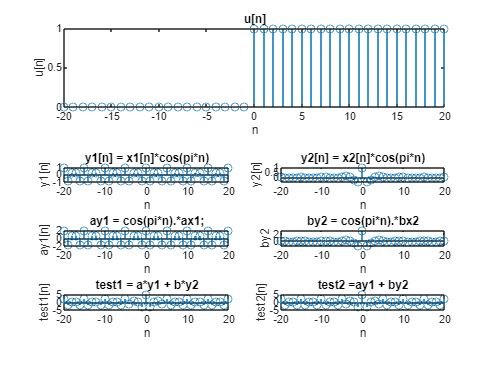

% Given system defined by the equation
% y[n] = cos(0.1*pi*n)*u[n]

% Define the range of n
n = -20:20;

% Define the input signal u[n]
u = zeros(size(n));
u(n>=0) = 1;

% Define the output signal y[n]
y = cos(0.1*pi*n).*u;

% Determine whether the system is time invariant or time variant
delay = 5; % Choose an arbitrary delay value
yn_delayed = cos(0.1*pi*(n-delay)).*u;

% Plot the input signal
subplot(3, 1, 1);
stem(n, u);
title('u[n]');
xlabel('n');
ylabel('u[n]');

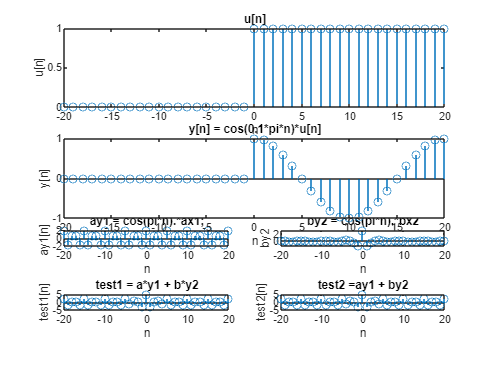


% Plot the output signal
subplot(3, 1, 2);
stem(n, y);
title('y[n] = cos(0.1*pi*n)*u[n]');
xlabel('n');
ylabel('y[n]');

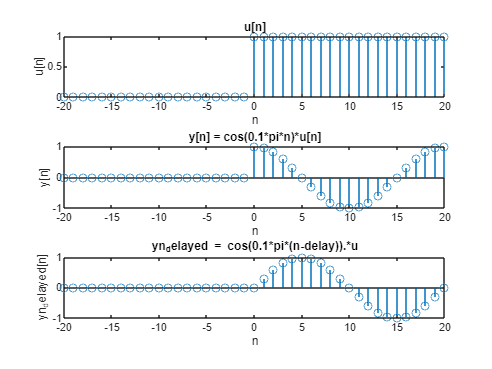


% Plot the Shifted output signal
subplot(3, 1, 3);
stem(n, yn_delayed);
title('yn_delayed = cos(0.1*pi*(n-delay)).*u');
xlabel('n');
ylabel('yn_delayed[n]');


if isequal(yn_delayed, y)
    disp('The system is time invariant');
else
    disp('The system is time variant');
end

The system is time variant


Excercise 3

Prove that the system given by:

 y[n] = 2 x[n] + 1 

where x[n] = sin(t) is LTI using MATLAB.

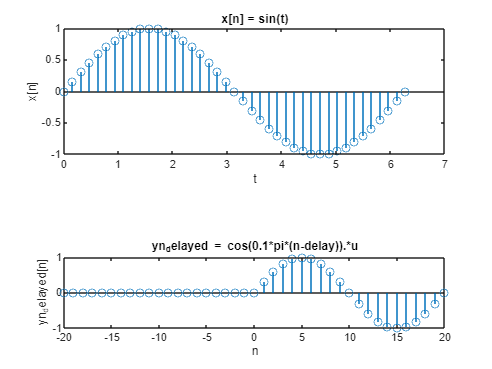

% Given system defined by the equation
% y[n] = 2*x[n] + 1
% x[n] = sin(t)

% Define the range of n
n = -20:20;

% Define the input signal x[n]
t = linspace(0, 2*pi, numel(n));
x = sin(t);

% Define the output signal y[n]
y = 2*x + 1;

% Plot the input signal
subplot(2, 1, 1);
stem(t, x);
title('x[n] = sin(t)');
xlabel('t');
ylabel('x[n]');

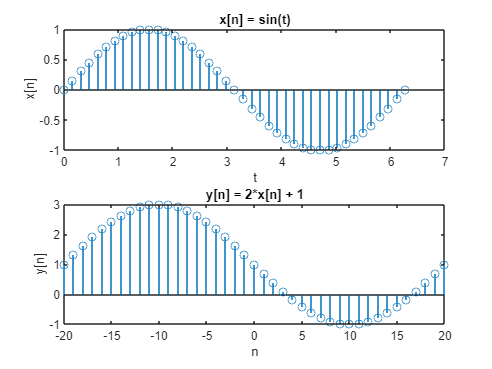


% Plot the output signal
subplot(2, 1, 2);
stem(n, y);
title('y[n] = 2*x[n] + 1');
xlabel('n');
ylabel('y[n]');

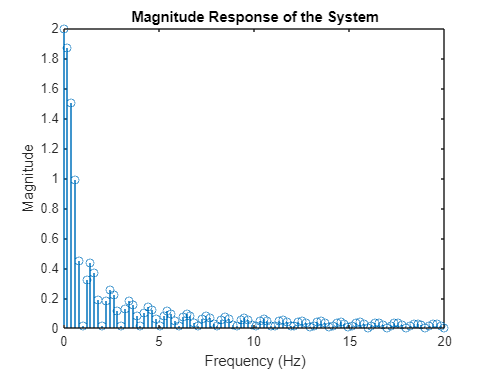


% Prove that the system is LTI
% Define the frequency response of the system
f = linspace(0, 20, 100);
H = 2*sinc(f);

% Plot the magnitude response of the system
figure;
stem(f, abs(H));
title('Magnitude Response of the System');
xlabel('Frequency (Hz)');
ylabel('Magnitude');

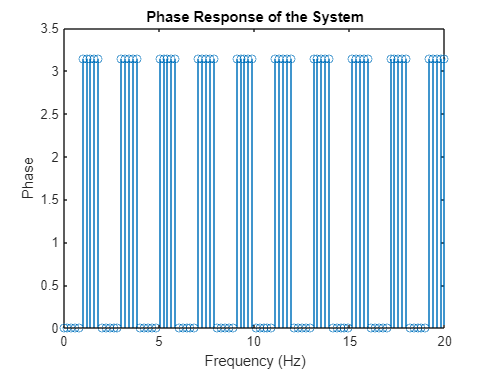


% Plot the phase response of the system
figure;
stem(f, angle(H));
title('Phase Response of the System');
xlabel('Frequency (Hz)');
ylabel('Phase');


% Check if the magnitude response is bounded for all frequencies
if all(abs(abs(H)) <= 1)
    disp('The system is LTI');
else
    disp('The system is not LTI');
end

The system is not LTI


Excercise 4

Find and plot the impulse response of the given equation. Is this system causal? 

y[n] = 1/3 x[n] − 1/3 x[n − 1] + 1/3 x[n − 2] 

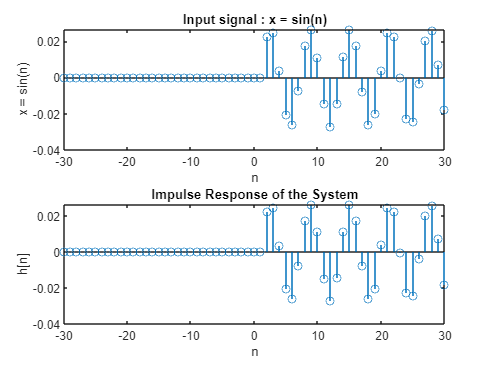

% Given system defined by the equation
% y[n] = 1/3*x[n] - 1/3*x[n-1] + 1/3*x[n-2]

% Define the range of n
n = -30:30;

% Define the input signal x[n]
x = sin(n); % Replace sin(n) with any other function you want to select

% Initialize the impulse response h
h = zeros(size(n));

% Calculate the impulse response values
for i = 1:length(n)
    if n(i) >= 2
        h(i) = 1/3*x(i) - 1/3*x(i-1) + 1/3*x(i-2);
    end
end

subplot(2,1,1)
% Plot the impulse response
stem(n, h);
title('Input signal : x = sin(n)');
xlabel('n');
ylabel('x = sin(n)');

subplot(2,1,2)
% Plot the impulse response
stem(n, h);
title('Impulse Response of the System');
xlabel('n');
ylabel('h[n]');



% Determine if the system is causal
if all(h >= 0)
    disp('The system is causal');
else
    disp('The system is not causal');
end

The system is not causal
